## First-order ARX model with one delay

Model: $(q + a_1) y(k) = (b_0 q + b_1) q^{-1}u(k) + e(k+1)$

z = tf('z', 1);
disp('True transfer function')

True transfer function


G0 = (z+0.9)/(z*(z-0.8))

G0 =
 
    z + 0.9
  -----------
  z^2 - 0.8 z
 
Sample time: 1 seconds
Discrete-time transfer function.



disp('Error transfer function')

Error transfer function


Ge = z/(z-0.8)

Ge =
 
     z
  -------
  z - 0.8
 
Sample time: 1 seconds
Discrete-time transfer function.



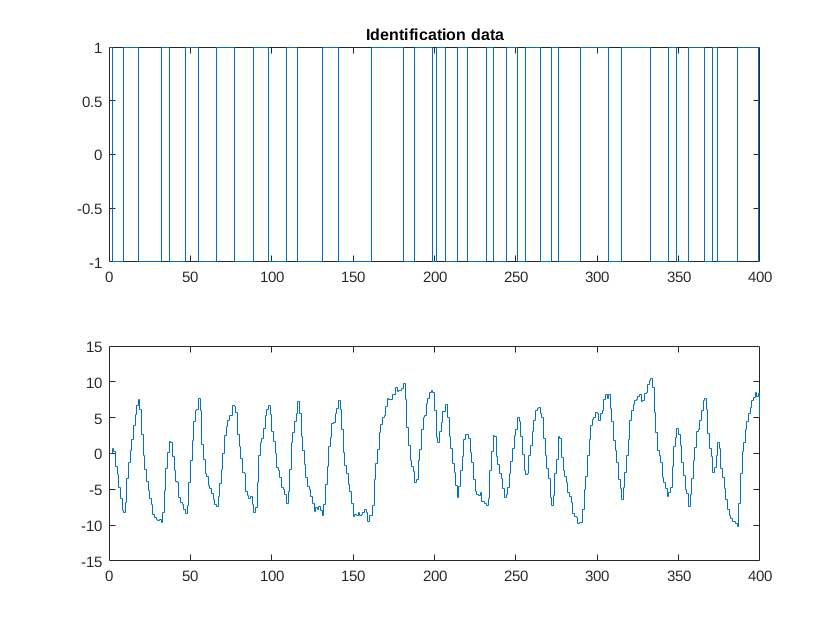


% Generate some data
% Input data
u1uv = idinput(800,'rbs',[0 0.2]); % Default is a rbs input signal
u1 = u1uv(1:400); % Split into data for identification and data for validation
u1v = u1uv(401:end);

% Perturbation-free output
y10 = lsim(G0, u1);
y10v = lsim(G0, u1v);
% Output with perturbation
e = randn(size(u1uv));
y1 = y10 + 0.5*lsim(Ge, e(1:400));
y1v = y10v + 0.5*lsim(Ge, e(401:800));

%Plot the data
figure()
subplot(211)
stairs(u1);
title('Identification data')
subplot(212)
stairs(y1)

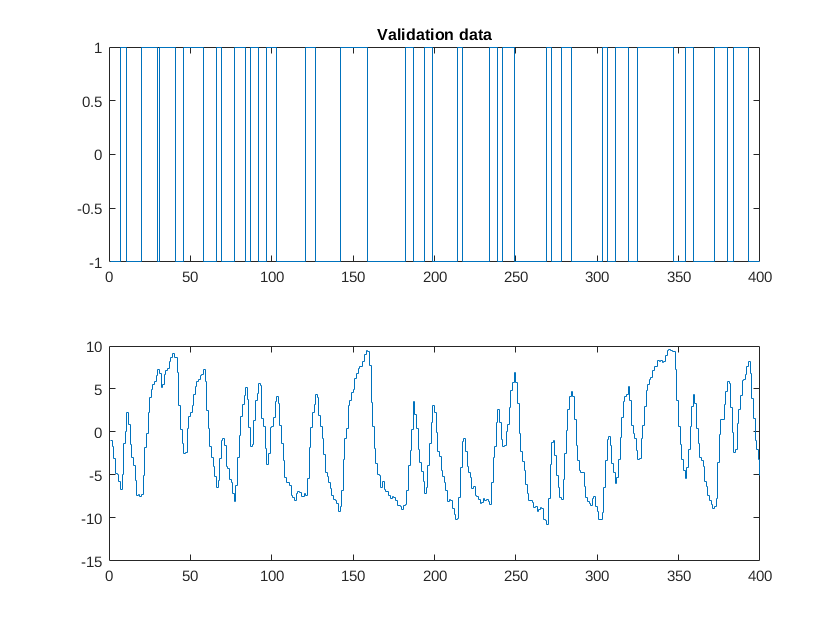


figure()
subplot(211)
stairs(u1v);
title('Validation data')
subplot(212)
stairs(y1v)

### Estimate the parameters

The one-step ahead predictor:


$$ \hat{y}(k+1) = -a_1y(k) + b_0u(k) + b_1u(k-1) = \pmatrix{ -y(k) & u(k) & u(k-1)} \pmatrix{ a_1 \cr b_0 \cr b_1}
 = \varphi_{k+1}^T\theta$$


The residual vector:


$$\epsilon = y - \Phi\theta$$


%Form the Phi matrix
Phi = cat(2, -y1(2:end-1), u1(2:end-1), u1(1:end-2));
% Form the y vector
y = y1(3:end);
theta1 = Phi\y;
disp('Estimated parameters:')

Estimated parameters:


fprintf('a_1 = %f', theta1(1))

a_1 = -0.809994

fprintf('b_0 = %f', theta1(2))

b_0 = 0.946417

fprintf('b_1 = %f\n', theta1(3))

b_1 = 0.901055


G11 = (theta1(2)*z + theta1(3))/(z*(z+theta1(1)))

G11 =
 
  0.9464 z + 0.9011
  -----------------
    z^2 - 0.81 z
 
Sample time: 1 seconds
Discrete-time transfer function.



% Using the sysid toolbox
arx121 = arx(iddata(y1, u1, 1), [1,2,1])

arx121 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 0.81 z^-1                             
                                                   
  B(z) = 0.9464 z^-1 + 0.9011 z^-2                 
                                                   
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=1   nb=2   nk=1
   Number of free coefficients: 3
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data.         
Fit to estimation data: 89.94% (prediction focus)
FPE: 0.3088, MSE: 0.3012                         


% Verify that it is the same model
minreal(G11 - arx121)

4 states removed.

ans =
 
  D = 
       u1
   y1   0
 
Static gain.



#### Fitting the wrong model


$$(q+a_1)y(k) = (b_0q + b_1)u(k) + e(k+1)$$


with one-step ahead predictor


$$ \hat{y}(k+1) = -a_1y(k) + b_0u(k+1) + b_1u(k) = \pmatrix{ -y(k) & u(k+1) & u(k)} \pmatrix{ a_1 \cr b_0 \cr b_1}
 = \varphi_{k+1}^T\theta$$


Phi = [-y1(1:end-1), u1(2:end), u1(1:end-1) ];
y = y1(2:end);
theta2= Phi\y;
fprintf('Estimated parameters')

Estimated parameters

fprintf('a_1 = %f\n', theta2(1))

a_1 = -0.866017


fprintf('b_0 = %f\n', theta2(2))

b_0 = -0.032504


fprintf('b_1 = %f\n', theta2(3))

b_1 = 1.581006


G12 = (theta2(2)*z + theta2(3))/(z+theta2(1))

G12 =
 
  -0.0325 z + 1.581
  -----------------
      z - 0.866
 
Sample time: 1 seconds
Discrete-time transfer function.



#### Fitting over-parameterized models

arx441 = arx(iddata(y1, u1, 1), [4,4,1])

arx441 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                   
  A(z) = 1 - 0.8409 z^-1 - 0.004872 z^-2 + 0.07946 z^-3 - 0.04467 z^-4
                                                                      
  B(z) = 0.9378 z^-1 + 0.8813 z^-2 - 0.09393 z^-3 + 0.1048 z^-4       
                                                                      
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=4   nb=4   nk=1
   Number of free coefficients: 8
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data.         
Fit to estimation data: 89.99% (prediction focus)
FPE: 0.3167, MSE: 0.2983                         


arx881 = arx(iddata(y1, u1, 1), [8,8,1])

arx881 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                                             
  A(z) = 1 - 0.8346 z^-1 - 0.01416 z^-2 + 0.1063 z^-3 - 0.09423 z^-4 - 0.0433 z^-5 + 0.0727 z^-6 - 0.008104 z^-7 - 0.004249 z^-8
                                                                                                                                
  B(z) = 0.9266 z^-1 + 0.8973 z^-2 - 0.09284 z^-3 + 0.09445 z^-4 - 0.003423 z^-5 - 0.08291 z^-6 + 0.02559 z^-7 - 0.04908 z^-8   
                                                                                                                                
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=8   nb=8   nk=1
   Number of free coefficients: 16
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data.         
Fit to estimation data: 90.13% (prediction f

arx16161 = arx(iddata(y1, u1, 1), [16,16,1])

arx16161 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                                                                            
                                                                                                                                                               
  A(z) = 1 - 0.8338 z^-1 - 0.02209 z^-2 + 0.1146 z^-3 - 0.09496 z^-4 - 0.041 z^-5 + 0.07083 z^-6 - 0.02039 z^-7 + 0.02439 z^-8 - 0.009524 z^-9 - 0.03168 z^-10 
                                                            + 0.0565 z^-11 + 0.01338 z^-12 - 0.0677 z^-13 + 0.02022 z^-14 - 0.01097 z^-15 + 0.01284 z^-16      
                                                                                                                                                               
                                                                                                                                                               
  B(z) = 0.9195 z^-1 + 0.9145

arx32321 = arx(iddata(y1, u1, 1), [32,32,1])

arx32321 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                                                                          
                                                                                                                                                             
  A(z) = 1 - 0.85 z^-1 - 0.03113 z^-2 + 0.1659 z^-3 - 0.1218 z^-4 - 0.06597 z^-5 + 0.1125 z^-6 - 0.02128 z^-7 - 0.008512 z^-8 - 0.00525 z^-9 - 0.01951 z^-10 
          + 0.04552 z^-11 + 0.005575 z^-12 - 0.01357 z^-13 - 0.01251 z^-14 + 0.02764 z^-15 - 0.03474 z^-16 + 0.03435 z^-17 - 0.02672 z^-18 + 0.0149 z^-19    
          - 0.04349 z^-20 - 0.006847 z^-21 + 0.03842 z^-22 + 0.002685 z^-23 + 0.008811 z^-24 - 0.08048 z^-25 + 0.07123 z^-26 - 0.03662 z^-27 + 0.05124 z^-28 
                                                                                        - 0.05754 z^-29 + 0.04896 z^-30 - 0.008796 z^-31 - 0.007728 z^-32    
                                         

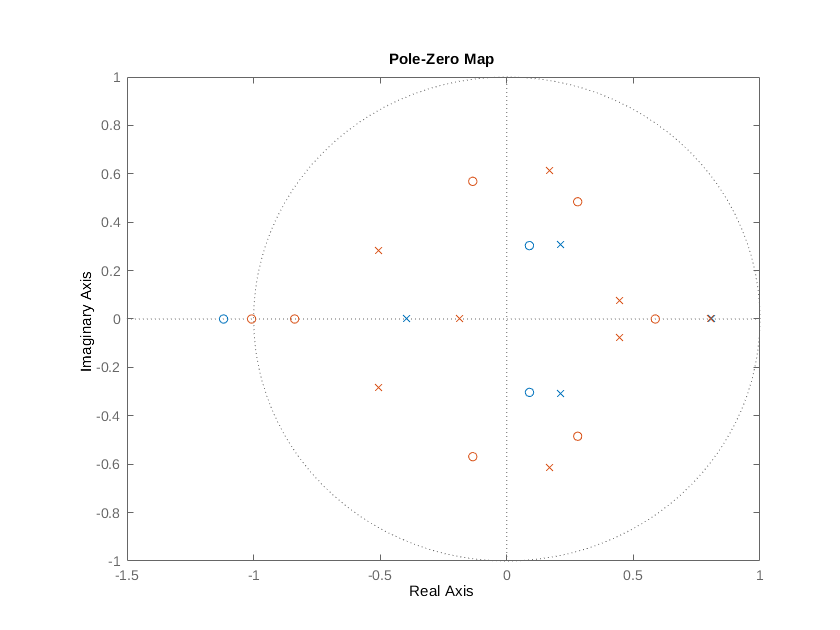

figure
pzmap(arx441, arx881)

#### Compare the models

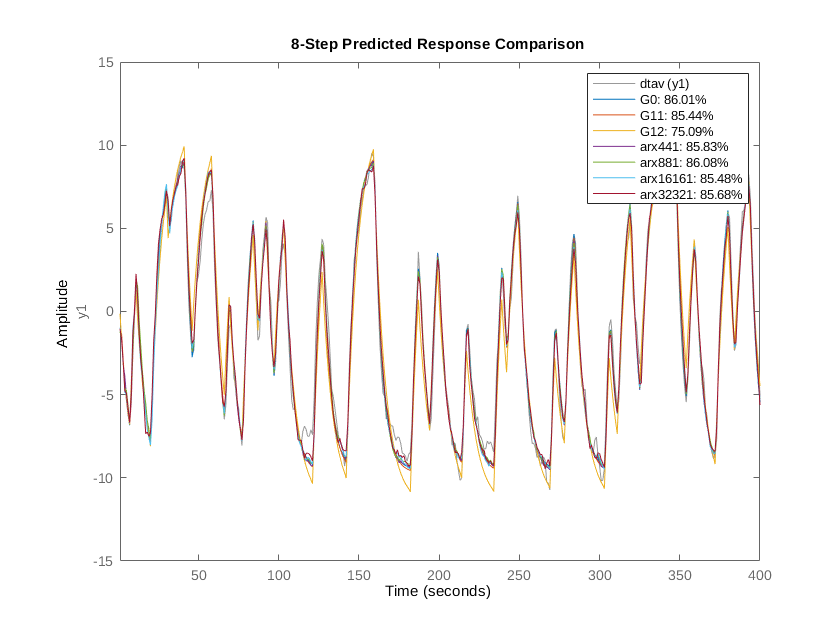

dta = iddata(y1, u1, 1);
dtav = iddata(y1v, u1v, 1);
figure
compare(dtav, G0, G11, G12, arx441, arx881, arx16161, arx32321, 8)

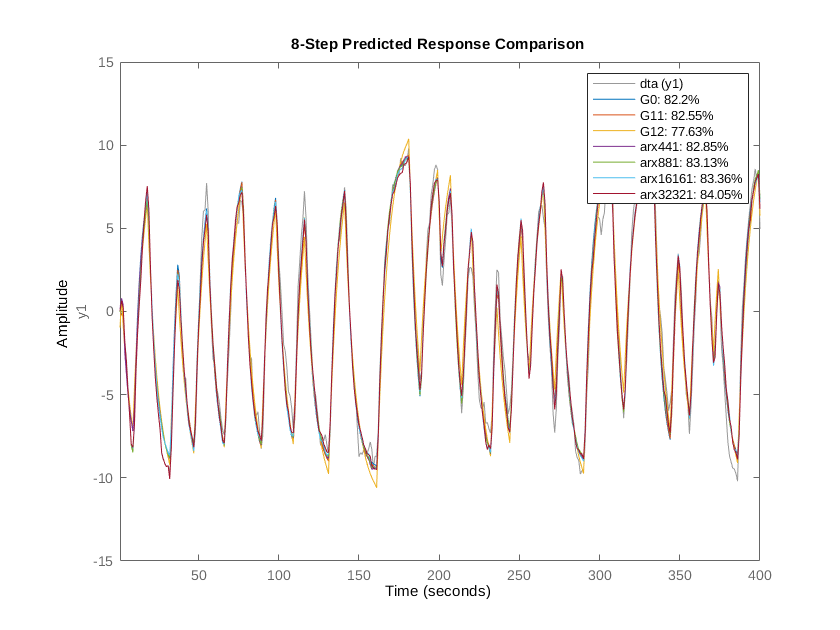

compare(dta, G0, G11, G12, arx441, arx881, arx16161, arx32321, 8)

Residual analysis, using ARX models estimated with the sysid toolbox.

G11a = arx(dta, [1, 2, 1])

G11a =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 0.81 z^-1                             
                                                   
  B(z) = 0.9464 z^-1 + 0.9011 z^-2                 
                                                   
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=1   nb=2   nk=1
   Number of free coefficients: 3
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "dta".   
Fit to estimation data: 89.94% (prediction focus)
FPE: 0.3088, MSE: 0.3012                         


G12a = arx(dta, [1, 2, 0])

G12a =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 0.866 z^-1                            
                                                   
  B(z) = -0.0325 + 1.581 z^-1                      
                                                   
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=1   nb=2   nk=0
   Number of free coefficients: 3
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "dta".   
Fit to estimation data: 86.69% (prediction focus)
FPE: 0.538, MSE: 0.5273                          


% Akaike information criterion
aic(G11a, G12a, arx441, arx881, arx32321)

Model quality according to the "nAIC" measure:
   -1.1749   -0.6199   -1.1498   -1.1173   -0.9026



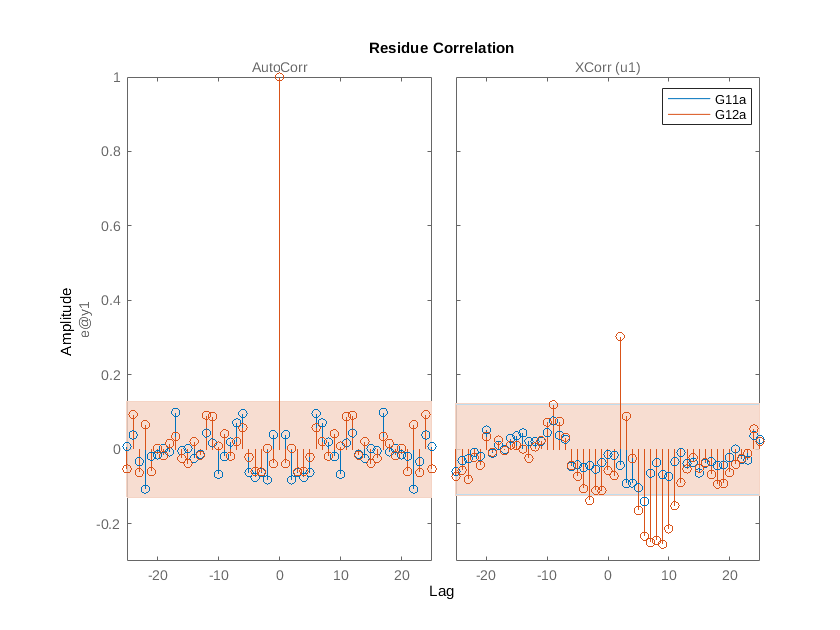

figure
resid(dtav, G11a, G12a)
legend